%%Dynamics of Planar Mechanisms, lab work 1
%Done by;
%Gateru Felix Wanyoike    -- ENM221-
%Washington Kigani Kamadi -- ENM221-0063/2017
%Michael Kimani Gitau     -- ENM221-
%Brown                    -- ENM221-

%Section a
%An implementation of The Chebyshev spacing formula is created as a
%   function called chebyshev
%It takes 3 arguments, the maximum and minimum value of the range and the
%   number of precision points.

%%Using chebyshev to find the precision points
%The precision points are stored in a column vector called precisionPoints
precisionPoints = chebyshev(15, 165, 3);

input = precisionPoints

input =   154.9519
   90.0000
   25.0481


%The required function
% theta4 = 65 + 0.43*theta2
%The above is implemented as a function taking one argument for theta2 and
%   giving as output theta4

output = rel(input)

output =   131.6293
  103.7000
   75.7707


%Solving for the values of K1, K2 and K3 using the freudenstein's equation
K = (freudenstein(input, output));

%Solving for the lengths of the links
%a,b and c -- given that the length of d is fixed
d = 0.410

d = 0.4100

a = abs(d*(K(1,1)))

a = 2.9111

c = abs(d*(K(2,1)))

c = 1.3977

b = sqrt((a^2)+(c^2)+(d^2) - (2*a*c*(K(3,1))))

b = 4.0466


%%Solving for the transmission angles
%Using the range of input angles from 30 degrees to 150degrees
input = (30: 5: 150)'

input =     30
    35
    40
    45
    50
    55
    60
    65
    70
    75


%%Computing the transmission angle
transmission = transmissionAngle(a,d,c,d,input)

transmission =    -3.8860
   -3.9836
   -4.0942
   -4.2170
   -4.3509
   -4.4951
   -4.6483
   -4.8095
   -4.9774
   -5.1506


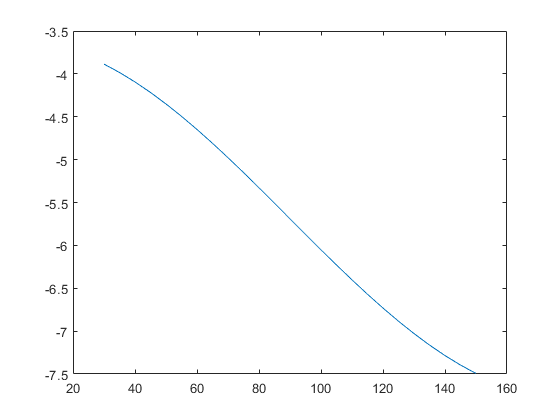

%%Plotting the values of the transmission angle against the input angle
plot(input, transmission )